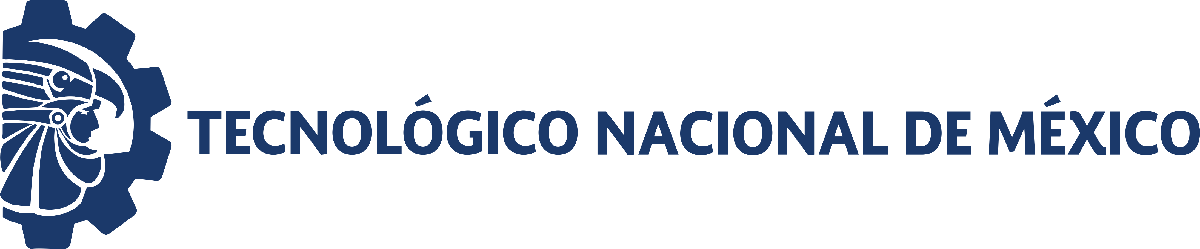                                 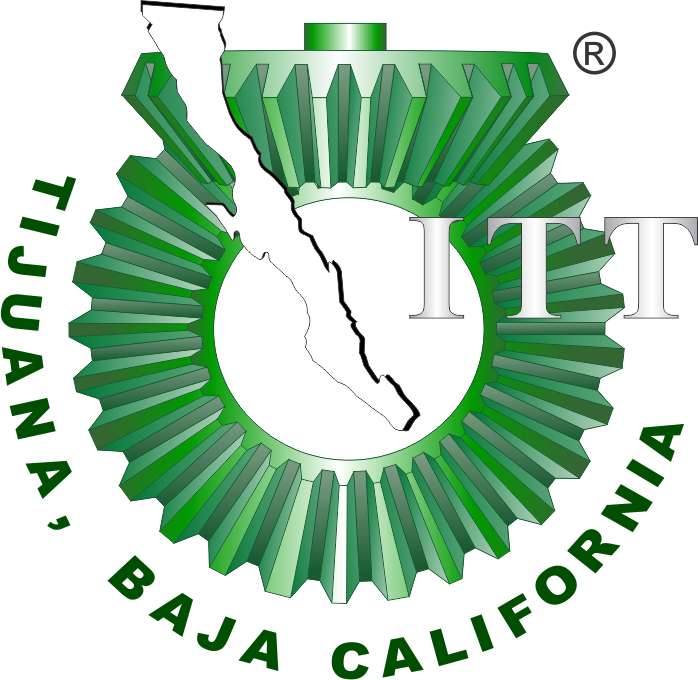

# Práctica IV: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

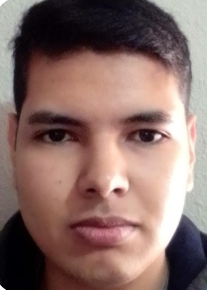

Nombre del alumno: Chávez González Roberto

Número de control: 22210884

Correo institucional: l22210884**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema4';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## **Respuesta del sistema**

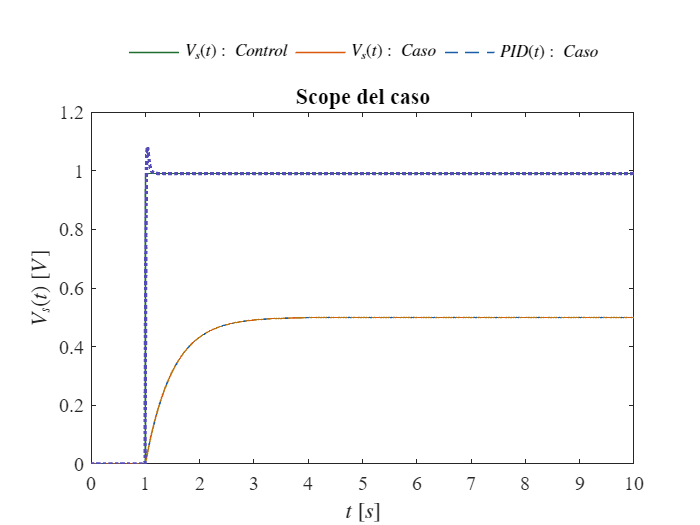

plotsignals(x.t, x.Ve, x.Control, x.Caso, x.PID1)

xlim([0.00 10.00])
ylim([0.00 1.20])

## Función de respuesta al sistema

function plotsignals(t, Ve, Control, Caso, PID1)

set(figure(), 'Color', 'w')

set(gca, 'Units', 'centimeters', 'Position', [1, 1, 25, 20])

thecolors = [0.12, 0.43, 0.19;
            0.85, 0.35, 0.05;
            0.09, 0.37, 0.65;
            0.73, 0.46, 0.07;
            0.33, 0.29, 0.72];

colororder(thecolors)


 


% gráfica: scope de caso
subplot(1, 1, 1);
box on; hold on;
P = plot(t, Control, '-', t, Caso, '-', t, Caso, '--', t, Caso, '-.', t, PID1, ':', 'LineWidth', 1);
set(P(5), 'LineWidth', 2)
L = legend('$V_s(t):\ Control$',   ...
           '$V_s(t):\ Caso$', ...
           '$PID(t):\ Caso$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'NorthOutside', ...
       'Box', 'Off', 'Orientation', 'Horizontal');
xlabel('$t$ $[s]$',      'Interpreter', 'Latex', 'FontSize', 12)
ylabel('$V_s(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 12)
xlim([0, 10]); xticks(0:1:10);
ylim([0, 1.2]); yticks(0:0.2:1.2);
T = title("Scope del caso");
set(T, 'FontSize', 12);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

exportgraphics(gcf, 'sistema_endocrino.pdf', 'ContentType', 'vector')
end